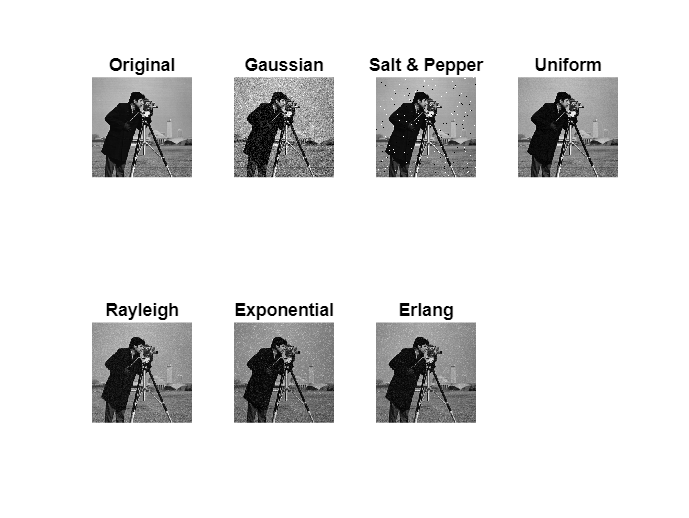

I = imread('cameraman.png');
I = im2double(I);
[M,N] = size(I);
gaussianNoise = imnoise(I,'gaussian',0,0.01);
spNoise = imnoise(I,'salt & pepper',0.02);
uniformNoise = I + 0.05*(rand(M,N)-0.5); 
uniformNoise = mat2gray(uniformNoise);
sigma_r = 0.05; 
U = rand(M,N);
rayleighNoise = I + sigma_r*sqrt(-2*log(1-U));
rayleighNoise = mat2gray(rayleighNoise);
lambda = 0.05;
U = rand(M,N);
expNoise = I - lambda*log(1-U); 
expNoise = mat2gray(expNoise);
k=2; 
theta=0.025; 
U1=rand(M,N); 
U2=rand(M,N);
erlangNoise = I - theta*log(1-U1) - theta*log(1-U2);
erlangNoise = mat2gray(erlangNoise);
figure;
subplot(2,4,1), imshow(I), title('Original');
subplot(2,4,2), imshow(gaussianNoise), title('Gaussian');
subplot(2,4,3), imshow(spNoise), title('Salt & Pepper');
subplot(2,4,4), imshow(uniformNoise), title('Uniform');
subplot(2,4,5), imshow(rayleighNoise), title('Rayleigh');
subplot(2,4,6), imshow(expNoise), title('Exponential');
subplot(2,4,7), imshow(erlangNoise), title('Erlang');

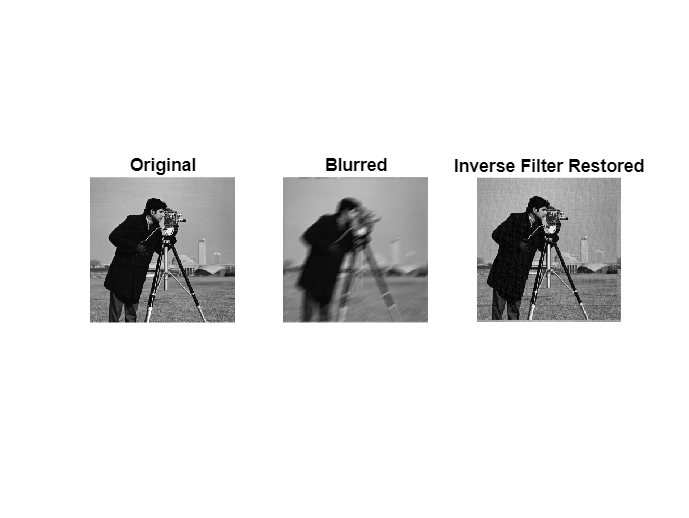

LEN = 15; THETA = 30;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(I, PSF, 'conv', 'circular');
G = fft2(blurred);
H = fft2(PSF, M, N);
threshold = 0.01;
H(abs(H)<threshold)=threshold;
F_inverse = G ./ H;
f_inverse = mat2gray(abs(ifft2(F_inverse)));
figure;
subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(blurred), title('Blurred');
subplot(1,3,3), imshow(f_inverse), title('Inverse Filter Restored');

fprintf('PSNR blurred: %.2f dB\n', psnr(blurred,I));

PSNR blurred: 20.33 dB


fprintf('PSNR inverse restored: %.2f dB\n', psnr(f_inverse,I));

PSNR inverse restored: 14.20 dB


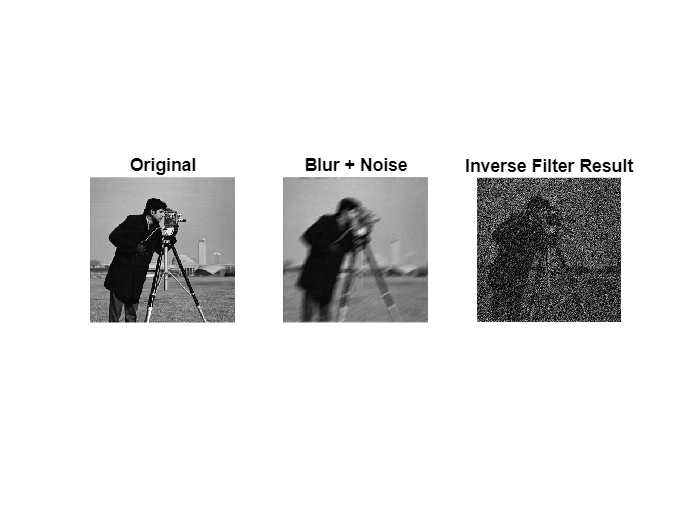

variance_noise = 0.0001;
blurred_noisy = imfilter(I, PSF, 'conv', 'circular');
blurred_noisy = imnoise(blurred_noisy, 'gaussian', 0, variance_noise);
G = fft2(blurred_noisy);
H = fft2(PSF, M, N);
H(abs(H)<threshold)=threshold;
F_inverse_noisy = G ./ H;
f_inverse_noisy = mat2gray(abs(ifft2(F_inverse_noisy)));
figure;
subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(blurred_noisy), title('Blur + Noise');
subplot(1,3,3), imshow(f_inverse_noisy), title('Inverse Filter Result');

fprintf('PSNR blurred+noise: %.2f dB\n', psnr(blurred_noisy,I));

PSNR blurred+noise: 20.29 dB


fprintf('PSNR inverse filter on noisy image: %.2f dB\n', psnr(f_inverse_noisy,I));

PSNR inverse filter on noisy image: 9.44 dB


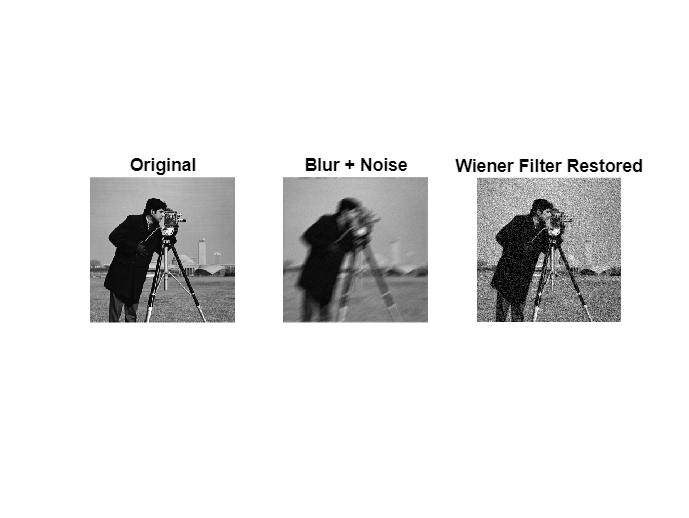

NSR = variance_noise / var(I(:));
restored_wiener = deconvwnr(blurred_noisy, PSF, NSR);
figure;
subplot(1,3,1), imshow(I), title('Original');
subplot(1,3,2), imshow(blurred_noisy), title('Blur + Noise');
subplot(1,3,3), imshow(restored_wiener), title('Wiener Filter Restored');

fprintf('PSNR Wiener restored: %.2f dB\n', psnr(restored_wiener,I));

PSNR Wiener restored: 20.11 dB
